# Frong Wing Editor

## Load base airfoil

% change file input based on front wing of your choosing from airfoil database
airfoilData = load("E423_FrontWing.txt"); 

## Front wing 1

A1 = AirfoilModifier(airfoilData, ...
    true, ... % flip
    10, ... % AOA
    10, ... % scale
    'A1_E423_FrontWing_Modified.txt');

A1.modify();

% translate from A2 
xVal = 9;
yVal = 2.5;
A1.airfoilCoordinates(:, 1) = A1.airfoilCoordinates(:, 1) - xVal; 
A1.airfoilCoordinates(:, 2) = A1.airfoilCoordinates(:, 2) - yVal; 

A1.exportAirfoil();

## Front wing 2

A2 = AirfoilModifier(airfoilData, ...
    true, ... % flip
    35, ... % AOA
    6, ... % scale
    'A2_E423_FrontWing_Modified.txt');

A2.modify();
A2.exportAirfoil();

## Front wing 3 (optional)

A3 = AirfoilModifier(airfoilData, ...
    true, ... % flip
    50, ... % AOA
    3, ... % scale
    'A3_E423_FrontWing_Modified.txt');

A3.modify();

% translate from A2
xVal = 4.3;
yVal = 3.8;
A3.airfoilCoordinates(:, 1) = A3.airfoilCoordinates(:, 1) + xVal; % x
A3.airfoilCoordinates(:, 2) = A3.airfoilCoordinates(:, 2) + yVal; % y

A3.exportAirfoil();

## Plot all 2-3 wings

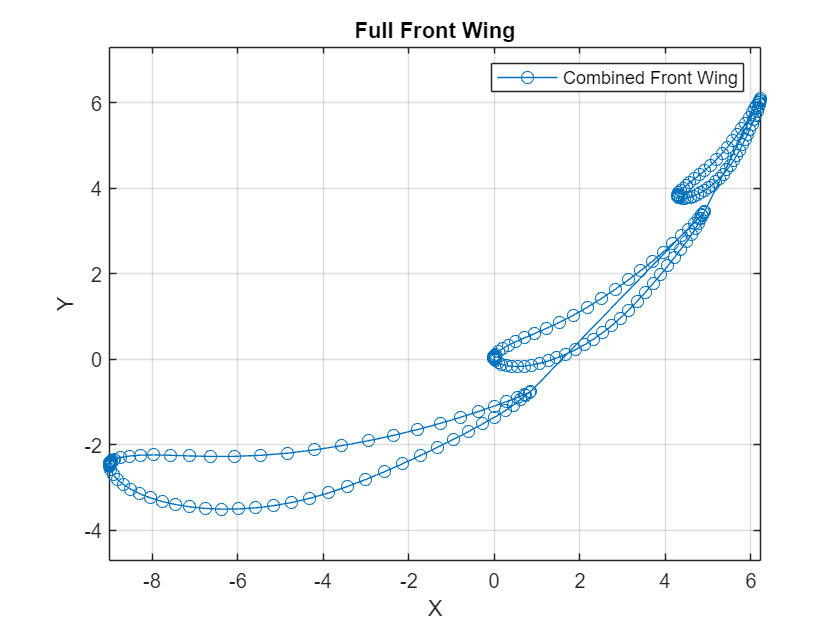

% Concatenate coordinates
combinedCoordinates = [A1.airfoilCoordinates; A2.airfoilCoordinates; A3.airfoilCoordinates];
%combinedCoordinates = [A1.airfoilCoordinates; A2.airfoilCoordinates];

% Plot
figure;
plot(combinedCoordinates(:, 1), combinedCoordinates(:, 2), '-o', 'DisplayName', 'Combined Front Wing');
axis equal;
grid on;
xlabel('X');
ylabel('Y');
title('Full Front Wing');
legend('show');


% Print length
disp("Chord length of all elements: " + num2str(max(combinedCoordinates(:, 1)) - min(combinedCoordinates(:, 1))));

Chord length of all elements: 15.2284
